# EK 125 Project

**Group:**

- **Parker Dunn**

- **Brennan Lavoie**

- **Sam Yard**

clear all;
close all;

## Section: Introduction

Strokes are the 2nd leading cause of death globally, according to the World Health Organization (WHO). Over 10% of total deaths are the result of a stroke (Fedesoriano). The WHO has called the stroke, the ‘incoming epidemic of the 21st century’ (Sarikaya, Ferro & Arnold, 2015).  A stroke occurs when blood supply to part of the brain is cut off or reduced, preventing oxygen and nutrients from reaching brain cells. Without oxygen or nutrients brain cells begin to die after just minutes. Many strokes are preventable (Guzik & Bushnell, 2017). Some risk factors leaving one more susceptible to a stroke include hypertension (high blood pressure), smoking, diabetes mellitus (which results in elevated levels of blood glucose), a previous stroke, and obesity (Guzik & Bushnell, 2017). If there was a way to predict the likelihood of a patient developing a stroke, how many lives would we be able to save with effective medical interventions and/or lifestyle changes? Our selected dataset outlines this potentially relevant patient information to predict if a patient is more prone to have a stroke.

References

Fedesoriano (Ed.). (2021, January 26). Stroke prediction dataset. Retrieved April 04, 2021, from https://www.kaggle.com/fedesoriano/stroke-prediction-dataset

Guzik, A., & Bushnell, C. (2017). Stroke Epidemiology and Risk Factor Management. Continuum (Minneapolis, Minn.), 23(1, Cerebrovascular Disease), 15–39. https://doi.org/10.1212/CON.0000000000000416

Sarikaya, H., Ferro, J., & Arnold, M. (2015). Stroke prevention--medical and lifestyle measures. European neurology, 73(3-4), 150–157. https://doi.org/10.1159/000367652

## Functions!!!!

*Hi Sam & Brennan,*

*    Sooo I'm not sure if it was what caused my MATLAB to "crap out" on HW 4, but I am a little anxious about putting functions directly in a live script. I think it will help to do as much of our work in functions as possible, since quite a bit of the work will be repetitive, but I don't want to keep them in here.*

*    So, I'm hoping we can keep a nicely organized list of functions in this live script and upload/download the additional scripts with functions whenever someone downloads/uploads this script.*

*    For the time being, my plan will be to frequently create functions for any number of tasks that I'm working on, then I will move them with this script and enter information about them here (along with comments in the function obviously).*

*-P Dunn*

#### Function: preview_data.m

- Purpose: This function extracts a set of fields and rows from the primary data structure, the table "strokedata," in order to display some part of the table.

- Syntax (for calling): *output_table = preview_data(entire_table, fieldslogical, rowselect, rowrange)*

- I wrote this function primarily to experiment with portions of the imported data.

- It didn't end up being very elaborate (in other words, the function is pretty short and maybe didn't warrant so much effort to be created), but some of the concepts can be reused for data extraction at other points.

- Inputs:

- (1) *entire_table* - used to pass in a table to extract from; set to simply take "strokedata" right now.

- (2) *fieldslogical* - In the script, there is space for someone to select which of the 12 fields from "strokedata" that they want to extract. That information is translated into a logical array that is passed into the function with this argument. In the function, this logical vector is used to extract the fields from the data table.

- (3) *rowselect* - passes in 1 or 2 to indicate whether all rows or a certain row range is desired from the "strokedata" table.

- (4) *rowrange* - a vector of the rows that you want to be extracted. This is only used if *rowselect = 2 *so the function knows to extract only some rows from the "strokedata" table.

- Output:

- *preview_table* - output is a subset of the "strokedata" table that was requested based on the inputs.

#### Function: bin_conditional_extract.m

- Purpose: To repetitively extract a set of rows from a field/column based on a condition in another field. The function should be able to extract data from certain subjects (i.e. rows) in a field of interest (the target field) based on the binary information in another field (conditional field).

- Syntax (for calling):

- ...to be continued

- Inputs:

- (1) *data_table* - the argument where the "strokedata" table is passed to the function

- (2) *targ_col* - the name or number of the field where the extracted data will come from

- (3) *cond_col* - the name or number of the field that will be used to determine if a row will be extracted

- (4) *condition* - must be a 1 or 0 (in the current configuration) and represents what elements should be extracted - e.g. condition == 1 ... then 1 must be in cond_col for the data in that row to be extracted.

- Outputs:

- (1) *extracted_data_array* - the function will extract data based on a binary condition and this vector will return the data from "targ_col"  for the rows with the correct binary condition in "cond_col".

- (2) *varargout *- THIS IS AN OPTIONAL OUTPUT. If the output is not requested with bracket notation, then it will not be returned by the function. If this output is requested, it returns the data that did not satisfy the condition provided to the function. Essentially, it is the data that was "ignored" when extracting "extracted_data_array".

## Section: Loading Data

### Importing the Data and Brief Overview of the Data

Loading in the "*healthcare-dataset-stroke-data.csv*" data.

Make sure to **(1)** have the CSV* file in the working directory* and **(2)** *match the file name* used above (or change it below) to ensure this code will load the data.

%This version of the "readtable" call only reads in a subset of the file
%{
Commented this out cause we don't really need it

strokedata_sample = readtable("healthcare-dataset-stroke-data.csv",'Range','A1:L5');

%}

%This version of the "readtable" call loads in the entire stroke dataet
strokedata = readtable("healthcare-dataset-stroke-data.csv");


A little overview of the information loaded in "strokedata"

Fields - *Total of 12*

- "id"                               - A list of integers to identify the patients

- "gender"                       - Male or Female

- "age"                            - Integers

- "hypertension"             - Binary

- "heart_disease"           - Binary

- "ever_married"             - Yes/No

- "work_type"                 - Categorical information - strings

- "Residence_type"        - Categorical (urban or rural)

- "avg_glucose_level"    - Float value

- "bmi"                            - Float, Int, or N/A

- "smoking_status"        - Categorical

- "stroke"                        - Binary

### **Setting up a short preview section, including a function that loads any choice of rows and fields.**

## *****No need to use this section unless you want to preview some of the raw data from the CSV file***

Select the fields you want - enter 1 to extract the field or 0 to ignore the field

id_f                =  0;
gender_f            =  0;
age_f               =  1;
hypertension_f      =  0;
heart_disease_f     =  0;
ever_married_f      =  0;
work_type_f         =  0;
Residence_type_f    =  0;
avg_glucose_level_f =  0;
bmi_f               =  1;
smoking_status_f    =  0;
stroke_f            =  1;

%creating the vector passed to the function preview_data
log_vec = logical([id_f, gender_f, age_f, hypertension_f,heart_disease_f, ever_married_f, work_type_f, Residence_type_f, avg_glucose_level_f,bmi_f, smoking_status_f, stroke_f]);


Select the rows you want.

There are **two approachs you can use to extract rows.**

(1) Select specific rows - *see bullet points below*

- Sections of rows can be passed via colon notation (e.g., 10:1:100)

- The rows will be extracted in numerical order - e.g. if [10, 2, 100, 2000, 60] are requested the rows will be returned in the order [2, 10, 60, 100, 2000].

(2) Select all rows

% Enter selected method for extracting rows
% "all rows" = 1
% "specific rows" = 2
choice = 2;

% Enter the specific rows you want below
rowrange = [1:10];  % enter the row numbers in the vector

preview_table = preview_data(strokedata,log_vec,choice,rowrange);
%struct displays below

% PREVIEW DISPLAYS HERE
disp(preview_table);

    age    bmi     stroke
    ___    ____    ______

    67     36.6      1   
    61      NaN      1   
    80     32.5      1   
    49     34.4      1   
    79       24      1   
    81       29      1   
    74     27.4      1   
    69     22.8      1   
    59      NaN      1   
    78     24.2      1   



% Just clearing up some memory.
% No need to keep these variables.
clearvars id_f gender_f age_f hypertension_f heart_disease_f ever_married_f work_type_f Residence_type_f avg_glucose_level_f bmi_f smoking_status_f stroke_f;
clearvars log_vec rowrange choice;

## Section: Exploratory Data Analysis

*****Random comments are italicized! They are not meant to be part of the write up.*

*I was thinking that I would start by creating some normal distributions and basic statistics about the data.*

## First, let's look at what portion of the patients in the study had a stroke or didn't have a stroke.

It is good sampling practice and good for predictive models to consider both people who did and did not have a stroke. Individuals who had a stroke provide insight into common lifestyle choices that may lead to strokes. Meanwhile, the subjects who did not have strokes offer a baseline of comparison. While we may find a common lifestyle choice among subjects who had a stroke, this factor may also be common among people who did not have a stroke (and generally common among the collective participants in the study). This comparison will be valuable in determining predictive factors for strokes.

Since it will be beneficial to compare the two groups of stroke patients, the distribution of these patients will be examined first.

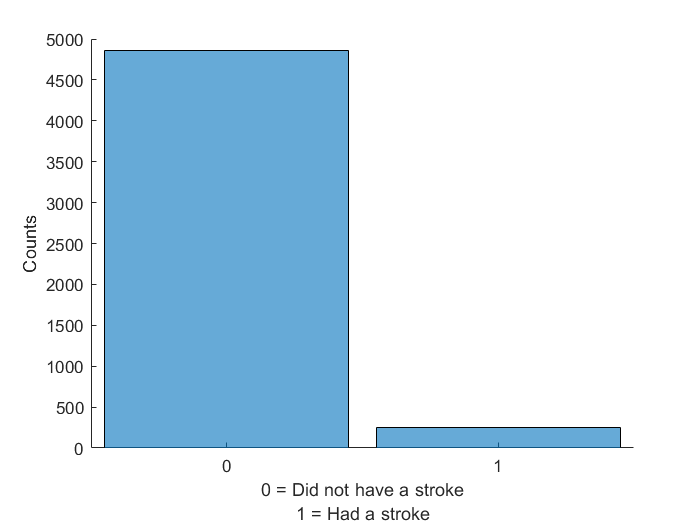

% Grabbing the "stroke" column of the table
stroke_col_array = strokedata.stroke;

stroke_dist_figure = figure(1);
clf(stroke_dist_figure)
hold on

stoke_dist = histogram(categorical(stroke_col_array),{'0','1'});
xlabel(["0 = Did not have a stroke","1 = Had a stroke"]);
ylabel("Counts")

hold off

% That count is really low. Determining the exact number of people who had
% a stroke
num_strokes = length(stroke_col_array(stroke_col_array == 1));
fprintf("There are %d individuals in the dataset who had a stroke.",num_strokes)

There are 249 individuals in the dataset who had a stroke.

Clearly, more patients were surveyed for this study that did not have a stroke compared to the small group of 249 poeple that did have a stroke. The sample size of patients with a history of stroke is small compared to the entire collection of people interviewed, which limits, to some degree, the value of any conclusions about strokes that we may develop from this data. The sample is probably a bit small to be able to generate robust predictions about a perosn's chancees of having a stroke. However, the primary focus here is to identify lifestyle features that correlate with risk of stroke. The large sample size of non-stroke patients means that any risk factor or lifestyle choice that clearly distinguishes the group of patients with a stroke from the rest of the patients is highly likely to be predictive of a stroke.

## Second, basic statistics about **gender**. Only one piece of information is available: how many males and how many females.

% Gotta grab the only information about gender.
gender_array = strokedata.gender;

% Determining all of the unique entries in this data
entry_types = unique(gender_array)

entry_types = 3×1 cell array
    {'Female'}
    {'Male'  }
    {'Other' }


% Now that we know what we are looking at, let's get a distribution of
% these entries
gender_categories = categorical({'Female','Male','Other'});
sort_gender_categories = reordercats(gender_categories,{'Female','Male','Other'});

These two lines are kind of fomatting related for the categories. More info here: [https://www.mathworks.com/help/matlab/ref/bar.html](https://www.mathworks.com/help/matlab/ref/bar.html)

Also, below I used a function that automatically counts categorical information -- "histcounts"

Information about histcounts can be found at: [https://www.mathworks.com/help/matlab/ref/histcounts.html](https://www.mathworks.com/help/matlab/ref/histcounts.html)

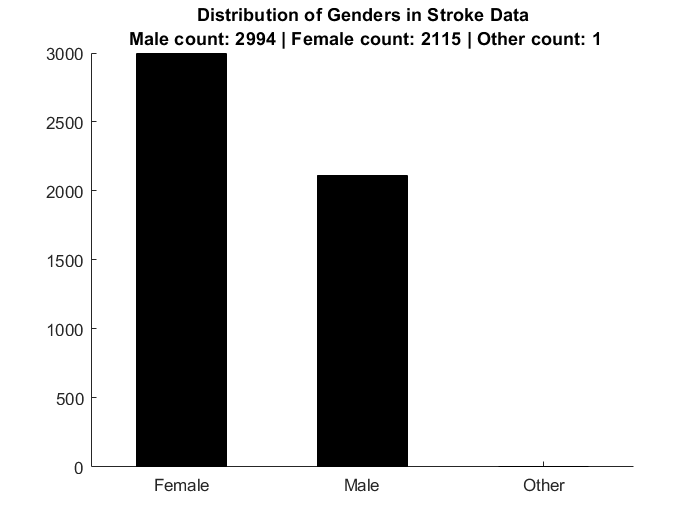

gender_dist_plot = figure(2);
clf(gender_dist_plot) %note: this just clears the figure so changes can be made and the old ones will disappear.
hold on
% grabbing the plotting values
gender_dist = histcounts(categorical(gender_array),sort_gender_categories);
%plotting the information
bar(sort_gender_categories,gender_dist,0.5,'k');
%interesting title for the plot
gender_plot_title = sprintf("Distribution of Genders in Stroke Data\n Male count: %d | Female count: %d | Other count: %d",...
                            gender_dist(1),gender_dist(2),gender_dist(3));
title(gender_plot_title);
hold off

clearvars gender_plot_title gender_dist gender_categories sort_gender_categories; % freeing up some computer space

## Third, basic statistics about age. Let's do some binning and look at the distribution.

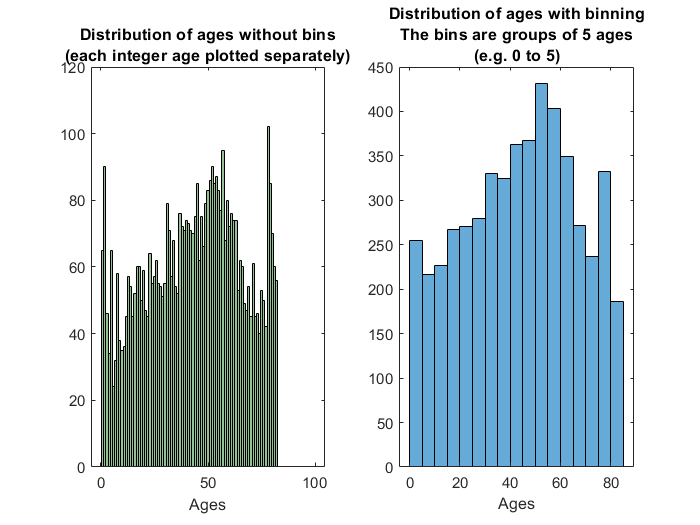

%grabbing the age data
age_array = strokedata.age;

%Going to do a subplot
% Subplot 1: All ages ... no binning
% Subplot 2: All ages ... binned within a range
%   (ex. bins of 5 years, 21-25 | 26-30 | 31-35 etc.)

age_distribution_plot = figure(3);
clf(age_distribution_plot)

hold on
subplot(1,2,1);
% PLOT 1 Script 
no_bins_edges = [0.5:1:99.5]; %Should indicate to "histogram" function what values we want in these bins.
age_no_bins_hist = histogram(age_array,no_bins_edges,'FaceColor',[0.3, .6, 0.3]);
%Modifying histogram
titleforsubplot1 = sprintf("Distribution of ages without bins\n(each integer age plotted separately)");
title(titleforsubplot1);
xlabel("Ages");

%PLOT 2 Script
subplot(1,2,2);
%going to use features of "historgram" function to do binning
age_bins_hist = histogram(age_array,'BinMethod','auto');

titleforsubplot2 = sprintf("Distribution of ages with binning\nThe bins are groups of %d ages\n(e.g. %d to %d)",...
                             (age_bins_hist.BinEdges(2)-age_bins_hist.BinEdges(1)),...
                              age_bins_hist.BinEdges(1), age_bins_hist.BinEdges(2));
title(titleforsubplot2)
xlabel("Ages")

hold off

clearvars age_no_bins_hist titleforsubplot1 titleforsubplot1 no_bins_edges; %freeing up computer space

The age distributions reveal some deviations from a normal data distrbitution. Age does not seem like a feature that would generally follow a normal distribution, but it's still important to keep of the trends in this data among the subjects.

In particular, it is interesting that the distribution of all ages has large spikes at very high and very low ages. The age 1 bin has nearly 100 subjects from the study. The study was conducted among patients in a hospital, so seeing 100 babies in a hospital is not unexpected since they likely make far more visits to doctors than the average healthy adult, but this group may need to be separated out when it comes to using this data for predicting strokes. **It is unlikely that babies and young children can effectively provide information about predicting the potential for a stroke.**

*Just wanted to throw a comment in here that the bolded line above is some of the stuff we should be looking to extract and talk about in EDA (exploratory data analysis). We very likely will have to filter out a group of ages, although there might be a more convenient way to do this then selecting an arbitrary age. For example, I'll bet the younger parts of the distribution have N/A for "work_type" so we can remove subjects below 40 and don't work or something. -- P Dunn*

***Next, we will extract the number of patients who have hypertension and look to see how many of them also had a stroke. ***

% Exploring the distribution of patients who had a stroke and hypertension

hypertension_mask = (strokedata.hypertension == 1);         % Extract a logical of patients who had a stroke
count_hypertension = sum(hypertension_mask);                % total number of people who had a stroke
hypertension_positive  = strokedata(hypertension_mask,:);   % table including only patients who have hypertension
stroke_mask = (hypertension_positive.stroke==1);            % Further extracting parts of the table: patients who have hypertension and had a stroke!
count_stroke = sum(stroke_mask);


percent_hypertension_stroke = (count_stroke/count_hypertension)*100;

fprintf("There were %d particiants who have a history of hypertension and %d of them also suffered a stroke.\n", count_hypertension, count_stroke);

There were 498 particiants who have a history of hypertension and 66 of them also suffered a stroke.


fprintf("This means that %.2f%% of the participants who have hypertension also suffered a stroke.\n", percent_hypertension_stroke);

This means that 13.25% of the participants who have hypertension also suffered a stroke.


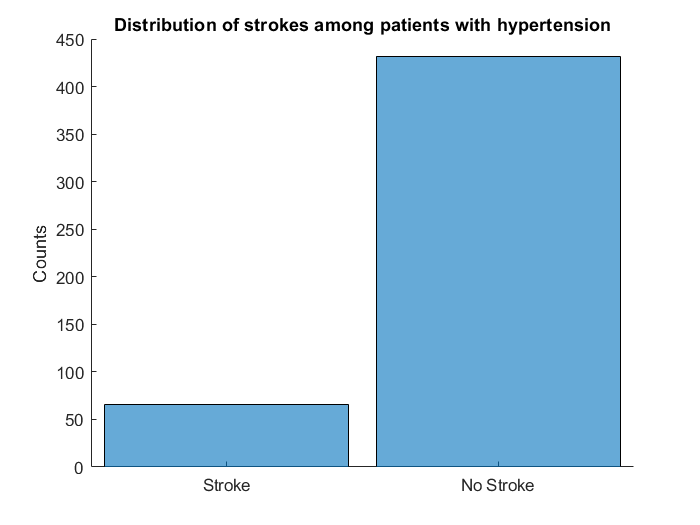

y1 = count_stroke;
y2 = count_hypertension - count_stroke;
figure(21);
clf(21);
hold on

%Just cleaned up the plot a little
histogram('Categories',{'Stroke','No Stroke'},'BinCounts',[y1, y2])
title("Distribution of strokes among patients with hypertension")
ylabel("Counts")
%{

x1 = 1;
x2 = 0;

bar(x2, y2);
hold on
bar(x1, y1);
legend('Hypertenion -stroke','Hypertension +stroke');
%}

hold off

***Now, we will extract the number of patients who have a history of heart disease and look to see how many of them also had a stroke.***


heart_mask = strokedata.heart_disease == 1;
count_heart = sum(heart_mask);
heart_positive  = strokedata(heart_mask,:);
heart_mask = heart_positive.stroke==1;
count_heart_stroke = sum(heart_mask);


percent_heart_disease_stroke = (count_heart_stroke/count_heart)*100;

fprintf("There were %d particiants have a history of heart disease and %d of them also suffered a stroke.\n", count_heart, count_heart_stroke);

There were 276 particiants have a history of heart disease and 47 of them also suffered a stroke.


fprintf("This means that %.2f%% of the participants who have hypertension also suffered a stroke.\n", percent_heart_disease_stroke);

This means that 17.03% of the participants who have hypertension also suffered a stroke.


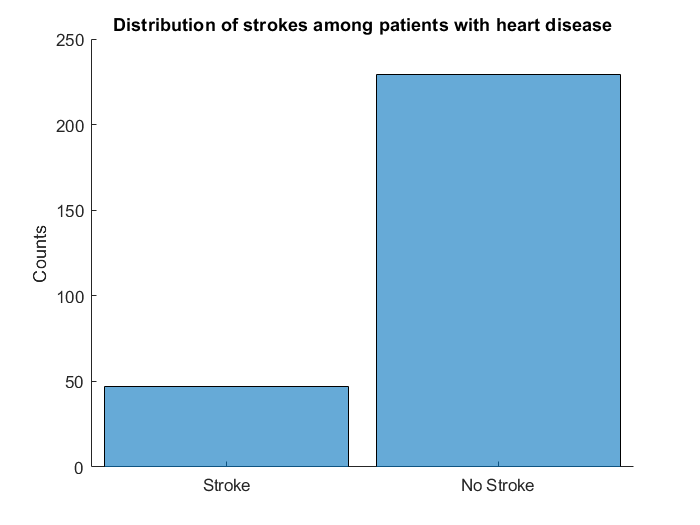


yhd1 = count_heart_stroke;
yhd2 = count_heart - count_heart_stroke;

figure(22);
clf(22);
hold on

%Just cleaned up the plot a little
histogram('Categories',{'Stroke','No Stroke'},'BinCounts',[yhd1, yhd2])
title("Distribution of strokes among patients with heart disease")
ylabel("Counts")

%{
xhd1 = 1;
xhd2 = 0;

figure(4)
bar(xhd2, yhd2);
hold on
bar(xhd1, yhd1);
legend('Heart Disease -stroke','Heart Disease +stroke');
%}
hold off

***We will now compare the number of strokes seen in patients who have a history of smoking/are currently smoking with the number of strokes seen in patients that never smoked. ***

*So, I'm going to try using a built-in function in MATLAB to do this instead of this approach. MATLAB is able to recognize and count categories in a table/array as long as it is told what the categories are.*

*(1) First, I will see what types of category entries we are working with*

*(2) Then, I will put these category entries into a cell array and use them to extract the number of occurences of each category.  (I will consolidate entries if there are variations of the same category - example: "Formerly smoked" vs "formerly smoked" ... I think these would be considered different.)*

*(3) I will get the counts of the categories using "histcounts" and try to get print outs like you were doing before*

*(4) Then i will try to plot all of the counts in a "histogram" plot*

%{
smokes_mask = strokedata.smoking_status == 'formerly smoked' || strokedata.smoking_status == 'smokes';
count_smokes = sum(smokes_mask);

smoking_array_entries = 4×1 cell array
    {'Unknown'        }
    {'formerly smoked'}
    {'never smoked'   }
    {'smokes'         }


smokes_positive  = strokedata(smokes_mask,:);
smokes_stroke_mask = smokes_positive.stroke==1;
count_smokes_stroke = sum(smokes_mask);

nonsmokes_mask = strokedata.smoking_status == 'never smoked';
count_nonsmokes = sum(nonsmokes_mask);

Unknown: 1544 counts
formerly smoked: 885 counts
never smoked: 1892 counts
smokes: 789 counts


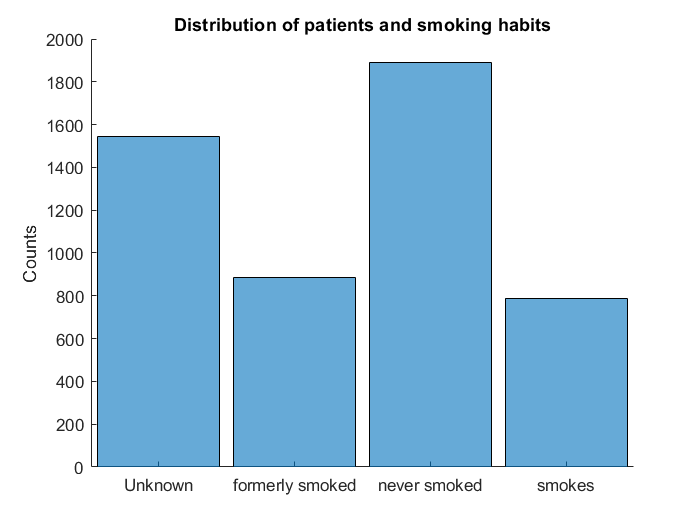

nonsmokes_positive  = strokedata(nonsmokes_mask,:);
nonsmokes_stroke_mask = nonsmokes_positive.stroke==1;
count_nonsmokes_stroke = sum(nonsmokes_mask);



percent_smokes_stroke = (count_smokes_stroke/count_smokes)*100;
percent_nonsmokes_stroke  = (count_nonsmokes_stroke/count_nonsmokes)*100;
%}


smoking_col_from_table = strokedata.smoking_status;
smoking_array_entries = unique(smoking_col_from_table) % just returns all the categories that we are looking for
[counts, order_of_counts] = histcounts(categorical(smoking_col_from_table),smoking_array_entries);

Counts is the number of appearances of each of the categories in "smoking_array_entries"

"Order_of_counts" should contain the same information as "smoking_array_entries", but is ordered to match the counts in the "Counts element"

for i = 1:length(counts)

There were 1674 particiants who formerly or currently smoke and 112 of them also suffered a stroke.


    fprintf("%s: %d counts\n",order_of_counts{i},counts(i))
end

This means that 6.69% of the participants who have formerly or currrently smoked also suffered a stroke.


figure(23);
clf(23);

There were 1892 particiants who never smoked and 90 of them also suffered a stroke./n

hold on

This means that 4.76% of the participants who have never smoked also suffered a stroke./n

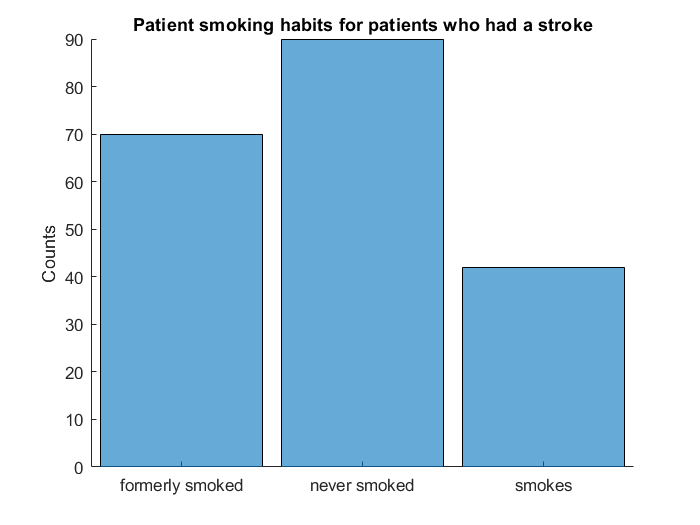


%Just cleaned up the plot a little
histogram('Categories',order_of_counts,'BinCounts',counts)
title("Distribution of patients and smoking habits")
ylabel("Counts")
hold off
[smoking_col_stroke_pos, smoking_col_stroke_neg] = bin_conditional_extract(strokedata,"smoking_status","stroke",1);

[counts2, order_of_counts2] = histcounts(categorical(smoking_col_stroke_pos),smoking_array_entries);
[counts3, order_of_counts3] = histcounts(categorical(smoking_col_stroke_neg),smoking_array_entries);


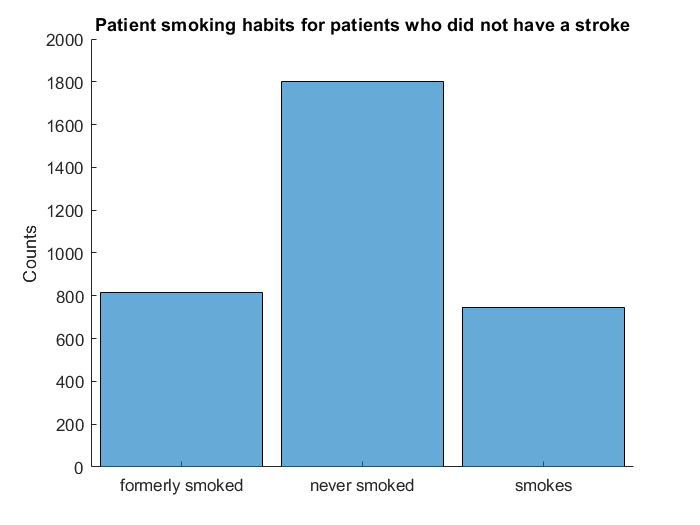

fprintf("There were %d particiants who formerly or currently smoke and %d of them also suffered a stroke.\n", counts(2) + counts(4), counts2(2) + counts2(4));
fprintf("This means that %.2f%% of the participants who have formerly or currrently smoked also suffered a stroke.\n",...
                                                                       (counts2(2) + counts2(4))/ (counts(2) + counts(4))*100);

fprintf("There were %d particiants who never smoked and %d of them also suffered a stroke./n", counts(3), counts2(3));
fprintf("This means that %.2f%% of the participants who have never smoked also suffered a stroke./n", (counts2(3)/counts(3)) * 100);

%Now, here is the information plotted


smoking_and_stroke_1 = figure(24);
%smoking_and_stroke_subplot.Position = [800 500 560 420] --- Ignore this
clf(24);
hold on
histogram('Categories',order_of_counts2(2:4),'BinCounts',counts2(2:4))
title("Patient smoking habits for patients who had a stroke")
ylabel("Counts")
hold off

smoking_and_stroke_2 = figure(25);
clf(25);
hold on
histogram('Categories',order_of_counts3(2:4),'BinCounts',counts3(2:4))
title("Patient smoking habits for patients who did not have a stroke")
ylabel("Counts")
hold off

*Yaaayyyy - smoking stuff is taken care of now at least.*

*I'm going to look into statistically proving that this (smoking_status) data and the age data distributions are statistically relevant. Like, there is not a significant statistical difference of smoking vs. non-smoking among stroke patients and non-stroke patients. -- P Dunn*

*(4) Avg glucose level - a historgram distribution of with the average glucose levels binned (like the age distribution)*

*(5) BMI - a historgram distribution of with the average glucose levels binned (like the age distribution)*

*etc.*

***"These features show/did not show there is or is not a correlation between strokes."***

## **Section:**** Goals and Hypotheses**

The goal of our script is to identify the attributes that affect the a persons risk of stroke, we can focus on attempting to cluster the attributes to find the patients with these attributes that most effectively might yield a successful predictor of future strokes. Since strokes are preventable, the people who fit into a highly predictive cluster could be alerted that they are at a high risk for stroke. Then they could  informed with any preventative steps they could take to decrease this risk. Based on our preliminary research, we hypothesize that 

## **Section:**** Data Scrubbing & Extraction**

*I have no idea if we really need this section or not. I figured I would create it in case anything came up that seemed to belong in this section. -- P Dunn*

## **Section:**** Data Analysis**

*I initially wrote this material in the "EDA" section, but decided it made more sense in this section. Sooo, I moved it down here randomly to be incorporated into this section later on. -- P Dunn*

#### Further exploration of age distribution based on other qualifying factors.

Age is an important qualifier in the context of lifestyle choices effecting a person's chances of having a stroke. It is likely at younger ages that strokes are frequently a result of other medical conditions rather than a child's lifestyle choices, which is what we are generally considering with this dataset. Similarly, elderly subjects in the study are more likely to have additional medical conditions that may play a role in their chances of having a stroke. The next step was to briefly investigate the age distributions of certain attributes (like whether or not someone had a stroke) based on ages.

- *Didn't get a chance to do it yet, but my next step was going to be plotting distributions of ages with the study subjects separated into two groups.*

- *Ex.** first I was going to separate the ages into two groups based on whether the participant had a stroke or not.*

%TESTING "bin_conditional_extract.m" for the first time

% This line uses "bin_conditional_extract" (read: "Binary Conditional
% Extract") to extract the ages (in a vector) of people who had a stroke
[ages_with_stroke, ages_no_stroke] = bin_conditional_extract(strokedata,"age","stroke",1);


Now that the ages have been separated into two groups, it is time to look at how ages are distributed for stroke patients compared to non-stroke patients.

age_distribution_stroke_conditional = figure(20); %20 is a random figure number
clf(age_distribution_stroke_conditional)

subplot(1,2,1)
%going to use features of "historgram" function to do binning
ages_stroke_patients = histogram(ages_with_stroke,'BinMethod','auto');

title_subplot1 = sprintf("Ages of stroke patients\nThe bins are groups of %d ages\n(e.g. %d to %d)",...
                             (ages_stroke_patients.BinEdges(2)-ages_stroke_patients.BinEdges(1)),...
                              ages_stroke_patients.BinEdges(1), ages_stroke_patients.BinEdges(2));
title(title_subplot1)
xlabel("Ages")


subplot(1,2,2)
ages_no_stroke_pats = histogram(ages_no_stroke,'BinMethod','auto');

title_subplot2 = sprintf("Ages of non-stroke patients\nThe bins are groups of %d ages\n(e.g. %d to %d)",...
                           (ages_no_stroke_pats.BinEdges(2)-ages_no_stroke_pats.BinEdges(1)),...
                           ages_no_stroke_pats.BinEdges(1), ages_no_stroke_pats.BinEdges(2));
title(title_subplot2)
xlabel("Ages")

hold off

Based on the plots above, it certainly looks like there is a correlation between age and a person's chances of having a stroke. This is useful information with regard to our end goal, understanding what risk factors can be used to predict a person's chances of having a stroke. Most importantly, this age information provides some valuable underlying context to the rest of our data analysis: young children and babies, who do not have useful inputs for many of the attributes investigated (like smoking status, BMI, hypertension, etc.), probably do not contribute helpful information about how these risk factors effect a person's chances of having a stroke. **Moving forward, it will likely be helpful to look at only patients in the age range 18+ becasue they are full grown adults that are more responsible for their lifestyle choices and accurate information about the relationships between the risk factors and stroke rates. The patients under 18 perhaps suffered a stroke due to other issues unrelated to lifestyle, such as other illnesses or having the genetic tendency for a stroke. **

*Oh... also, I'd say we can generally follow the process above (looking at distributions) to determine which risk factors are good predictors of strokes. This is a pretty simple approach, but yields easy to discuss results and doesn't over complicate things.*

*Now ... if we really wanna go next level with data analysis, I can try to bust out some cooler machine learning and linear algebra concepts. (I'm not sure what is actually in the machine learning toolbox) We just learned PCA in Lin Algebra and I could probably use that to come up with more information about how certain attributes effect stroke rate, but that's adding a lot of complexity and I'm not sure Prof Attaway or Leah is really expecting that from us. --- P Dunn*